# Radio Communication System

## *Simulation Script*

Authors:

Leonard Berresheim - s055126

Ali Jahanbakhsh       - s0

Mihail Milchev           - s056818

clc, clear variables; % clear all variables
addpath('subfunctions'); % add directory "subfunctions" to path

## Global Simulation Parameters

**ebN0dB **defines the **S**ignal to **N**oise **R**atio *(short SNR)* per Bit in dB for the **A**dditive **W**hite **G**aussian **N**oise *(short AWGN)* that will be applied on the mapped signal later on. The system will be tested with varrious values for SNR

ebN0dB = 0:30; % SNR (per bit) in dB
nBits = 10e3; % simulate nBits bits per simulation loop

**Constellation **is the modulation format that will be use to map the incoming bitsequence.

As an example, for the modulation format **Q**uadrature **P**hase **S**hift **K**ey *(short QPSK) *the bitsequence is mapped arcording to *Table 1.*

% Table 1
Dezimalzahl = [0;1;2;3];
Bitwert = dec2bin(Dezimalzahl);
Index = [1;2;3;4];
Konstellationspunkt = [-1-i;-1+i;1-j;1+j];
table(Bitwert,Dezimalzahl,Index, Konstellationspunkt)

ans = 4×4 table
    Bitwert    Dezimalzahl    Index    Konstellationspunkt
    _______    ___________    _____    ___________________

      00            0           1             -1-1i       
      01            1           2             -1+1i       
      10            2           3              1-1i       
      11            3           4              1+1i       


*Notice:* *the index value is shifted by 1 due to the fact that matlab starts indexing at 1 instead of 0*

constellation = [-1-1j, 1-1j, -1+1j, 1+1j]; % constellation of the
% modulation format, here: QPSK with gray mapping)
M = length(constellation);% Number of constellation Symbols

## Simulation loop

### Generating the bitsequence

**generateBits()** generates a random bitsequence of length **nBits**.

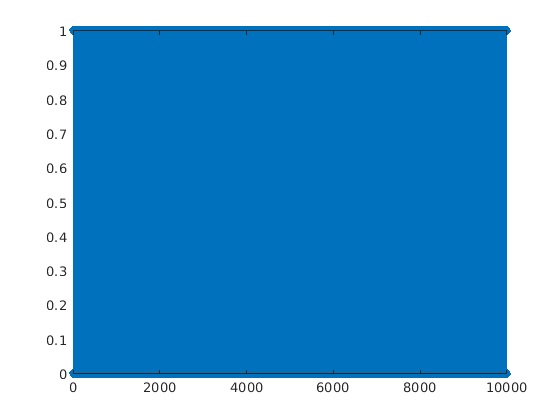

bits = generateBits(nBits);

### **Mapping the bitsequence**

**mapper() **maps the bitsequence **bits** according to the modulation format **constellation** defined before.

mapped_signal = mapper(bits, constellation);

### Adding AWGN to the mapped signal

**add_awgn() **adds the noise to the mapped signal **mapped_signal **for each SNR value in **ebN0dB**.

mapped_signal_noise = add_awgn(mapped_signal,ebN0dB,M);

### Demapping the signal

Due to the faultiness of the transmission canal signal at the output of the canal doesn't match the constellation points of the constellation format.

**decision() ** matches each constellation point of **mapped_signal_noise **to the nearest constellation point in **constellation;**

decided_signal = decision(mapped_signal_noise, constellation);

**demapper() **demappes the signal according to the constellation table.

As an example, for the modulation format **Q**uadrature **P**hase **S**hift **K**ey *(short QPSK) *the signal is demapped arcording to *Table 2.*

% Table 2
Dezimalzahl = [0;1;2;3];
Bitwert = dec2bin(Dezimalzahl);
Index = [1;2;3;4];
Konstellationspunkt = [-1-i;-1+i;1-j;1+j];
table(Konstellationspunkt,Index,Dezimalzahl, Bitwert)

ans = 4×4 table
    Konstellationspunkt    Index    Dezimalzahl    Bitwert
    ___________________    _____    ___________    _______

           -1-1i             1           0           00   
           -1+1i             2           1           01   
            1-1i             3           2           10   
            1+1i             4           3           11   


demapped_bits = demapper(decided_signal,constellation);

### Counting Errors

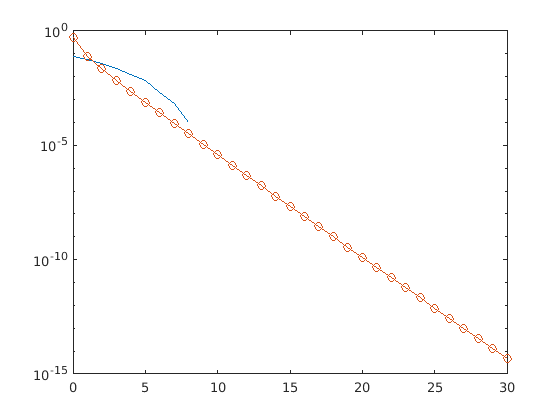

[nErr,ber] = countErrors(demapped_bits,bits);
% Numerische Berechnuns
P_AWGN = 0.5*erfc(sqrt(ebN0dB));

semilogy(ebN0dB, ber, ebN0dB, P_AWGN, "-o");



%fprintf("Anzahl der Fehler: " + nErr + "\n");
%fprintf("Fehlerverhältnis: " + ber*100 + "%%\n");